clear
clc

load('hall.mat');
[h,w] = size(hall_gray,[1 2]);
blockamountW = ceil(w/8);
blockamountH = ceil(h/8);

方法3：用[1 -1]替换zigzag扫描后最后一个非零值的后一位。若最后一位也非0，则直接替换该位

info = int32(randi([0 1],1,blockamountH*blockamountW));
info = 2*info-1;
[ACstream,DCstream,h,w] = DCTconceal3(hall_gray,info);
infoRtv = DCTretrieve3(ACstream,DCstream,h,w);

获取信息隐藏图像

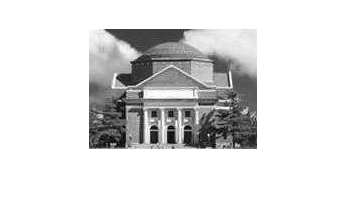

ImageConceal = JpegDecoder(DCstream,ACstream,h,w);
imshow(ImageConceal);

计算PSNR

MSE = sum((ImageConceal-hall_gray).^2,'all')/h/w;
PSNR = 10 * log10(255^2/MSE);

计算压缩率

compressrate = 8*h*w/(length(ACstream)+length(DCstream));

评估信息还原的准确率

ErrorMtx = bitxor(info,infoRtv); % 按位异或得错误
fidelity = 1-sum(ErrorMtx,"all")/h/w; % 还原率

PSNR = 33.1693, 33.2170, 33.2128, 33.1888, 33.2069

compressrate = 6.1916, 6.1916, 6.1916, 6.1916, 6.1916

fidelity = 1, 1, 1, 1, 1